## global body planner test

addpath(genpath('fpp_planner\'));
addpath(genpath('math\'));
x_init = [0;0;0; 0;0;0.3];
vel_tar = [0;0;0.05; 1;0;0];
horizon_num = 200;
dt = 0.05;
[state_traj] = body_traj_planner(x_init ,vel_tar, horizon_num, dt)

state_traj =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

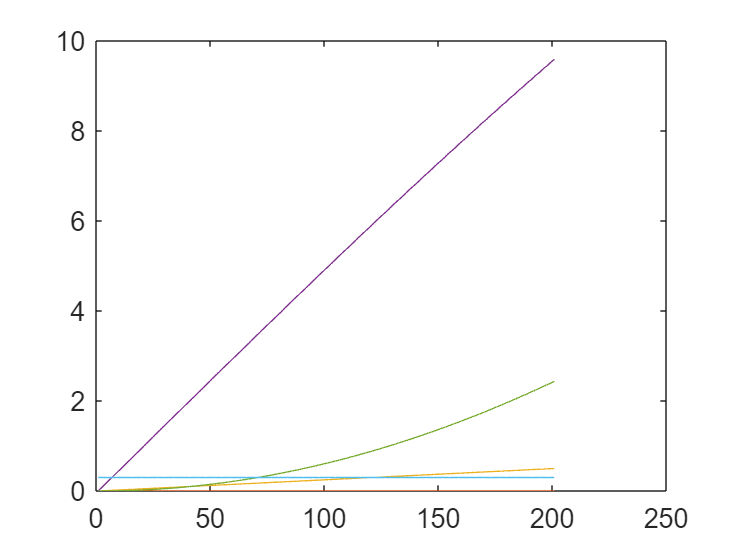


for i=1:6
plot(state_traj(i,:))
hold on
end

## local swing foot planner test

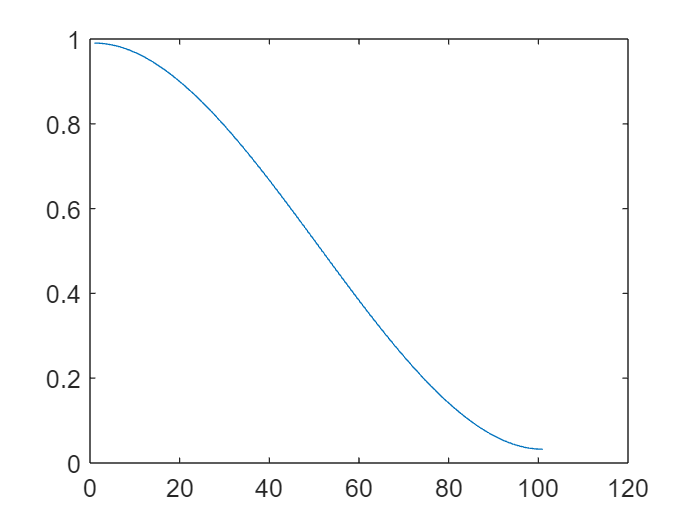

addpath(genpath('fpp_planner\'));
p_start = [0.990353;-1;0];
p_end = [0.032495;1;0.5];
fp_h = 1.5;
fpp_arr = [];

for t_sw = 0:0.01:1
    fpp_t = swing_fpp_planner(p_start,p_end,fp_h,t_sw);
    fpp_arr = [fpp_arr, fpp_t];
end

clf;
plot(fpp_arr(1,:));

## stance fpp planner

addpath(genpath('fpp_planner\'));
addpath(genpath('math\'));

[world_p, body_p, ctr_p, path]...
    = hardware_params();

x_init = [0;0;0; 0;0;0.3];
vel_tar = [0;0;0.05; 1;0;0];
horizon_num = ctr_p.mpc_horizon_steps;
dt_mpc = ctr_p.dt_mpc;

hip_vec_s = [body_params.length/2; body_params.width/2; 0];
hip_dir_mat = [1 1 -1 -1; 1 -1 1 -1; 0 0 0 0];
% each col is a hip vec
fpp_arr_t = hip_dir_mat .* repmat(hip_vec_s,1,4);

[state_traj] = body_traj_planner(x_init ,vel_tar, horizon_num, dt_mpc)

state_traj =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


[ref_fpp_traj, ref_contact_event, fpp_arr_n]...
    = stance_fpp_planner(state_traj, vel_tar, fpp_arr_t, world_p, body_p, ctr_p)

t_global_n = 1.0000e-08

ref_fpp_traj =     0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700
    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    

ref_contact_event =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     

fpp_arr_n =    16.4110   16.6224   16.2132   16.4247
    8.7800    8.6288    8.5035    8.3522
         0         0         0         0


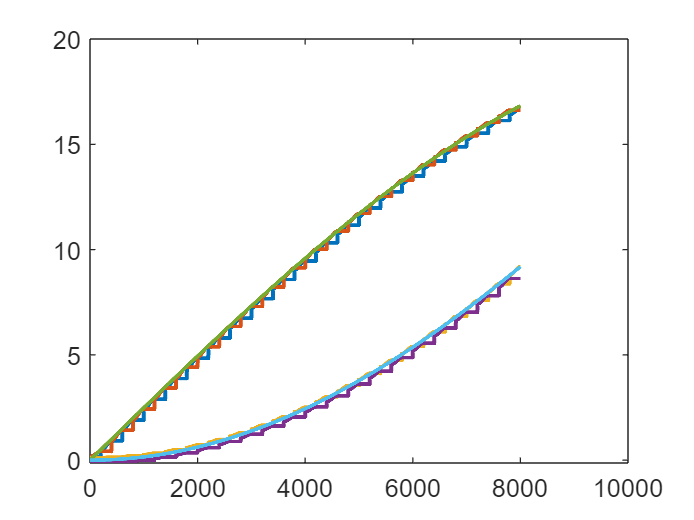

clf;
plot(ref_fpp_traj(1,:),'linewidth',1.5);
hold on
plot(ref_fpp_traj(4,:),'linewidth',1.5)
hold on
plot(ref_fpp_traj(2,:),'linewidth',1.5)
hold on
plot(ref_fpp_traj(5,:),'linewidth',1.5)
hold on

plot(state_traj(4,:),'linewidth',1.5)
hold on
plot(state_traj(5,:),'linewidth',1.5)
hold on


% %% Plots
% clf;
% subplot(1,2,1);
% plot(x_sol(4,:),"LineWidth",1.5);
% hold on;
% plot(x_sol(5,:),"LineWidth",1.5);
% hold on;
% plot(x_sol(6,:),"LineWidth",1.5);
% hold on;
% title("Body's Position")
% xlabel("Step")
% ylabel("m")
% legend("Position X","Position Y","Position Z");
% grid on  
% 
% subplot(1,2,2);
% plot(x_sol(1,:),"LineWidth",1.5);
% hold on;
% plot(x_sol(2,:),"LineWidth",1.5);
% hold on;
% plot(x_sol(3,:),"LineWidth",1.5);
% hold on;
% title("Body's Euler Angle")
% xlabel("Step")
% ylabel("rad")
% legend("Roll","Pitch","Yaw");
% grid on  
% 
% %% velocity plot
% clf;
% plot(x_sol(9,:),"LineWidth",1.5);
% hold on;
% plot(x_sol(10,:),"LineWidth",1.5);
% hold on;
% title("Body's Velocity")
% xlabel("Step")
% ylabel("m/s or rad/s")
% legend("Yaw Velocity rad/s","X Velocity m/s");
% grid on  
% 
% %% fpp
% clf;
% subplot(1,2,1);
% plot(fp_g_sol(1,:),"LineWidth",1.5);
% hold on;
% plot(fp_g_sol(2,:),"LineWidth",1.5);
% hold on;
% plot(fp_g_sol(3,:),"LineWidth",1.5);
% hold on;
% title("Foot Placement Point global of FL leg")
% xlabel("Step")
% ylabel("m")
% legend("Position X","Position Y","Position Z");
% grid on
% 
% subplot(1,2,2);
% plot(f_sol(1,:),"LineWidth",1.5);
% hold on;
% plot(f_sol(2,:),"LineWidth",1.5);
% hold on;
% plot(f_sol(3,:),"LineWidth",1.5);
% hold on;
% title("Ground Reaction Force of FL leg")
% xlabel("Step")
% ylabel("N")
% legend("Force X","Force Y","Force Z");
% grid on  
